# Train CycleGAN for Image Domain Conversion

This example shows how to train a cycle-consistent generative adversarial network (CycleGAN) for image-to-image translation.

A CycleGAN can be used to convert images of one type - or domain - into images of another domain [1]. Unlike some other image translation techniques, CycleGAN networks are trained using unsupervised learning. This means that you do not need a dataset of paired images that are the almost the same, apart from the desired domain modification. The model can be trained using randomly paired sets of images from the two domains.

CycleGAN networks can be used in the following applications:

- Style transfer

- Season conversion

- Day-to-night conversion 

- Object transformation

A generative adversarial network (GAN) is a type of deep learning network that can generate data with similar characteristics as the input training data.

A GAN typically consists of two networks that train together:

- Generator — Given an input, this network generates data with the same structure as the training data.

- Discriminator — Given batches of data containing observations from both the training data, and generated data from the generator, this network attempts to classify the observations as "real" or "generated".

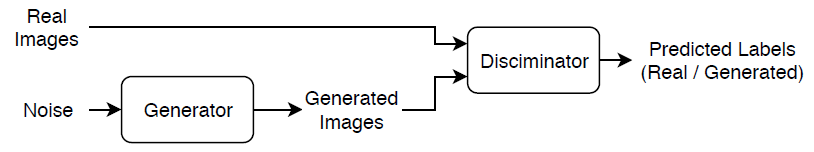

The CycleGAN model has two generators and two discriminators. One generator converts images from domain X into images of domain Y. The second generator converts images of domain Y into images of domain X. The discriminator networks attempt to tell the difference between the real and generated images from domains X and Y -  there is one discrimniator network for each domain. 

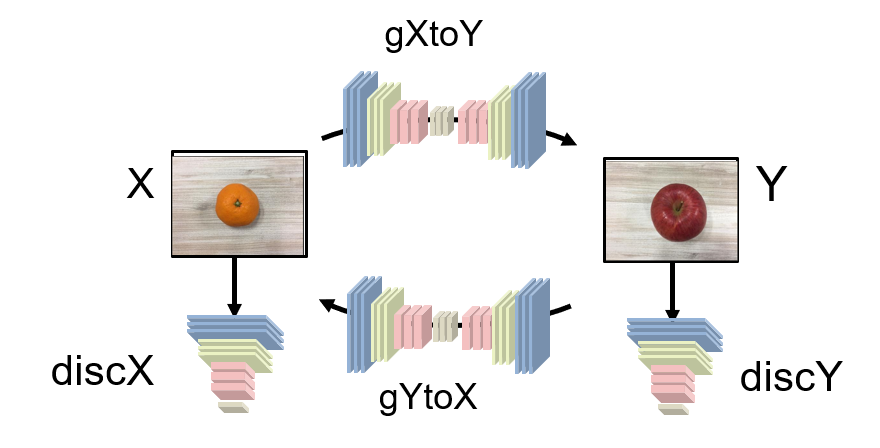

To train a CycleGAN, train all four networks simultaneously to maximize the performance:

- Train the generators to generate data that "fools" the discriminators.

- Train the discriminators to distinguish between real and generated data.

To maximize the performance of the generators, maximize the loss of the discriminator when given generated data. That is, the objective of each generator is to generate data that the discriminators classify as "real".

To maximize the performance of the discriminators, minimize the loss of the discriminator when given both real and generated labeled data. That is, the objective of each discriminator is to not be "fooled" by the generators.

Ideally, these strategies result in a network that generates convincingly realistic data and a discriminator that has learned strong feature representations that are characteristic of the training data for each domain.

## Load Training Data

Set `dataRoot` to the location of the data you downloaded from the repository. 

dataRoot = 'Orange2Apple';
dataTrainX = fullfile(dataRoot,'trainX');
dataTrainY = fullfile(dataRoot,'trainY');
dataTestX = fullfile(dataRoot,'testX');
dataTestY = fullfile(dataRoot,'testY');

Define the image size and create datastores containing the training and test images for both domains. The custom datastore `pairedImageDatastore` collects the image data so that unrelated pairs of images are delivered for training. 

imageSize = [128,128,3];

cgimdsTrain = cycleGanImageDatastore(imageSize,imageSize,dataTrainX,dataTrainY);
cgimdsTest = cycleGanImageDatastore(imageSize,imageSize,dataTestX,dataTestY);

View a selection of images from the training set.

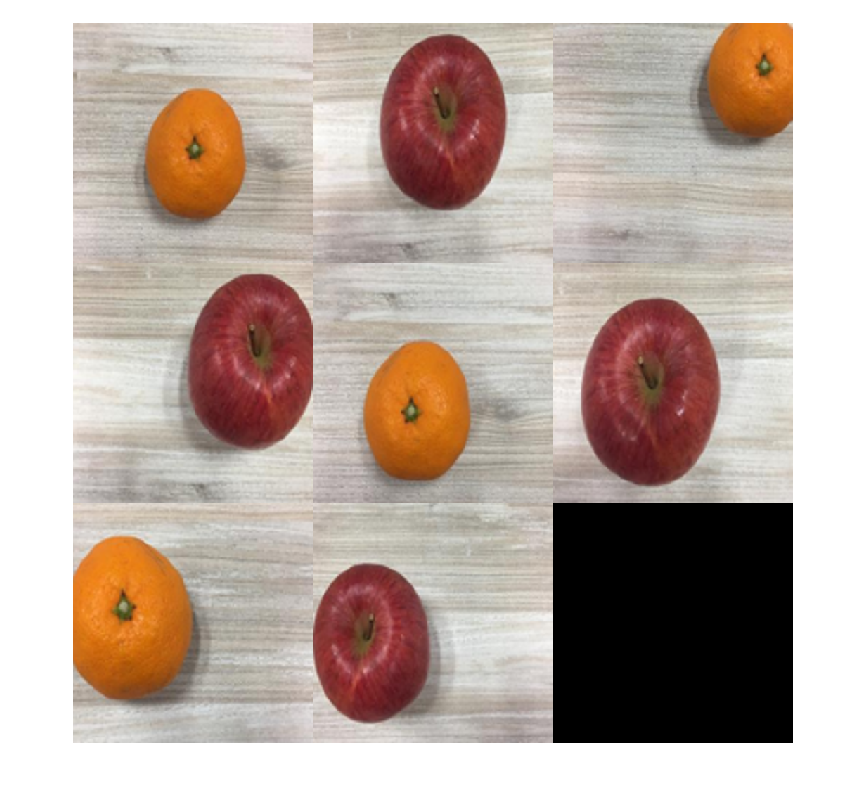

numImagePairs = 4;
imList = [];
for i = 1:numImagePairs
    imPair = read(cgimdsTrain);
    imX = imPair.X{1};
    imY = imPair.Y{1};
    imList = cat(4,imList,imX,imY);
end

figure
montage(imList)

The images are paired randomly and the contents do not match in terms of size and location in the image frame. 

## Define Generator and Discriminator Networks

Use the functions included in this repository to create the four generator and descriminator networks.  

### Generator Networks

The generator networks each consist of three parts: 

- an encoder network that encodes the feature representation of the image; 

- a transformer network consisting of a series of convolutional residual blocks;

- a decoder network that upsamples the transformed features and outputs the final generated image. 

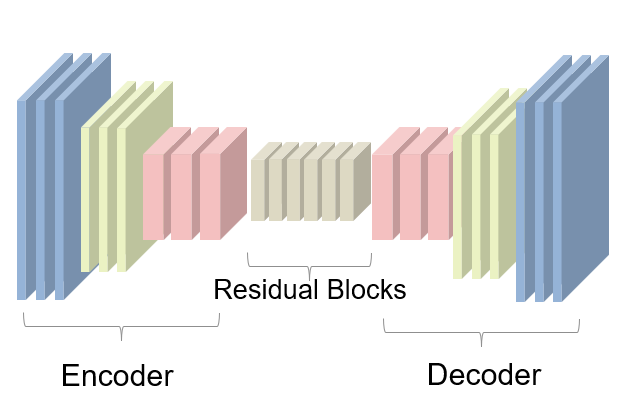

Define the convolutional depth of the encoder, the initial number of convolutional filters, the number of residual blocks. The initial number of filters defines the number of filters for the first convolutional layer; subsequent convolutions use double the number of filters of the previous convolution.

encoderDepth = 3;
numGeneratorFilters = 64;
numResiduals = 6;

generatorYtoX = generator(imageSize,imageSize,numGeneratorFilters,encoderDepth,numResiduals); % Generator for translating domain Y to domain X
generatorXtoY = generator(imageSize,imageSize,numGeneratorFilters,encoderDepth,numResiduals); % Generator for translating domain X to domain Y

### Discriminator 

The discriminator network has the structure of a PatchGAN network [2]. The network examines patches of the input image and dettermines the probability of the patch being real or fake.

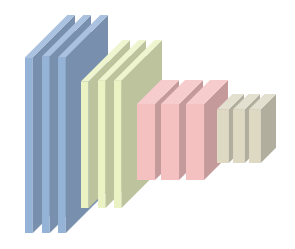

Specify the convolutional depth of the discriminator and the initial number of convolutional filters.

discriminatorDepth = 4;
numDiscriminatorFilters = 64; 

discrimatorX = discriminator(imageSize,discriminatorDepth,numDiscriminatorFilters); % Discriminator for X
discriminatorY = discriminator(imageSize,discriminatorDepth,numDiscriminatorFilters); % Discriminator for Y

## Define Model Gradients and Loss Functions

Create the `modelGradients` function, defined in the Supporting Functions section of this example, which takes as input the generator and discriminator networks and the input real images from both domains, and returns the generator and discriminator losses, the gradients of the losses with respect to the network learnable parameters, and the transformed image pairs.

The total loss for CycleGAN training is give by


$$\textrm{Loss}=\textrm{Adversarial}\;\textrm{Loss}+\lambda \times \textrm{Cycle}\;\textrm{Consistency}\;\textrm{Loss}$$


The parameter $\lambda$ controls the relative importance of the two types of loss.

### Adversarial (GAN) Loss

The adversarial loss is the typical GAN loss function. The objective of the generator is to generate data that the discriminator classifies as "real". The cycleGAN architecture uses the least squares loss function for the generator and discriminator networks.

The objective of the discriminator is to nor be "fooled" by the generator. To maximize the probability that the discriminator successfully discriminates between the real and generated images, minimize the square sum of the difference between expected and predicted output for real and generated output. The discriminator loss is given as


$$\textrm{lossDiscriminator}={\left(D\left(X\right)-1\right)}^2 +{D\left(X^{\prime } \right)}^2$$


where $X$ is a real input, $X^{\prime }$ is a generated input, and $D\left(X\right)$ is the result of the discriminator network applied to $X$. 

The objective of the generator is to generate images that the discriminator identifies as real. The generator loss is given as


$$\textrm{lossGenerator}={\left(D\left(X^{\prime } \right)-1\right)}^2$$


where $D\left(X^{\prime } \right)$ is the result of the discriminator network applied to the generated output $X^{\prime }$.

### **Cycle Consistency Loss**

The cycle consistency loss is specific to the training process of the CycleGAN model. The cycle consistency loss attempts to enforce consistency in the generator models such that transforming an image from domain X to domain Y using `generatorY`, and then transforming the result back to domain X using `generatorX` gives a good approximation of the original image. 

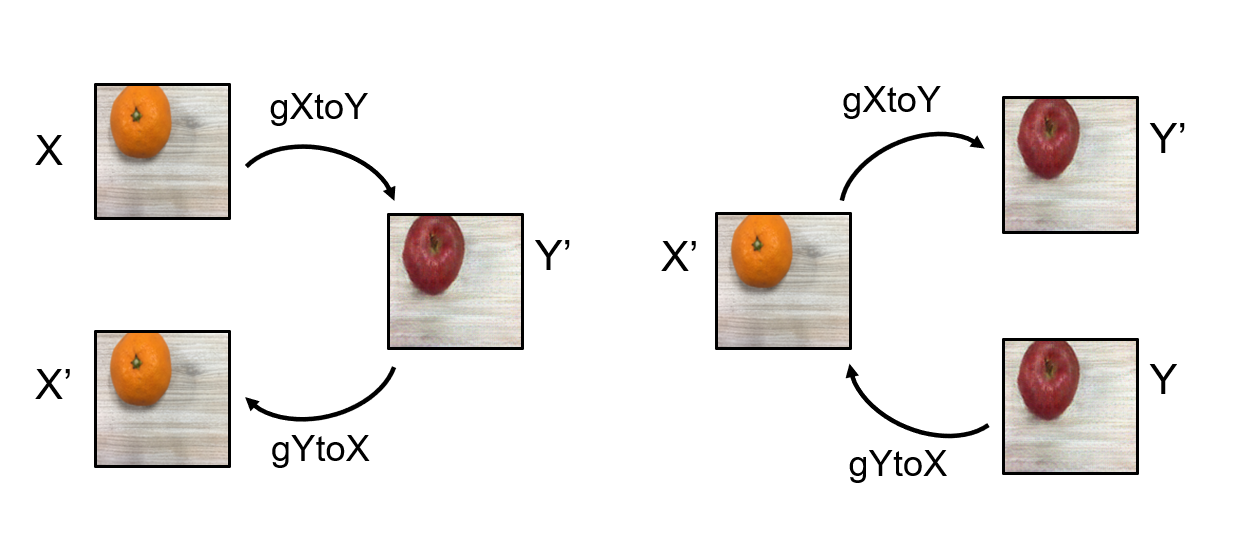

The cycle consistency loss can be expressed as


$$\textrm{lossCycle}=\left|Y-G_Y \left(G_X \left(Y\right)\right)\right|+\left|X-G_X \left(G_Y \left(X\right)\right)\right|$$


where $X$ and $Y$ are images from the two domains, and $G_X \left(Y\right)=X^{\prime }$ generates an image in domain X from a real image in domain Y. The difference between the original and the generated image reconstructed back into the original domain is the cycle consistency loss. As the training progresses, the reconstructed image closely match the original images.

## Specify Training Options

Set the `doTraining` flag to `true` if you want to train the model. If `doTraining` is `false`, the example loads the pretrained model supplied with this repository. 

doTraining = true;

Train with a mini-batch size of 1 for 1000 epochs.

numEpochs = 1000;
miniBatchSize = 1;
cgimdsTrain.MiniBatchSize = miniBatchSize;

Specify the options for Adam optimization. For all networks, use:

- A learning rate of 0.0002

- A gradient decay factor of 0.5

- A squared gradient decay factor of 0.999

learnRate = 0.0002;               
gradDecay = 0.5;
sqGradDecay = 0.999;

Train on a GPU if one is available. Using a GPU requires Parallel Computing Toolbox™ and a CUDA® enabled NVIDIA® GPU with compute capability 3.0 or higher.

executionEnvironment = "auto";

Save the model every 100 iterations.

saveFrequency = 100;

## Train Model

Train the model using a custom training loop. Loop over the training data and update the network parameters at each iteration. To monitor the training progress, display the scores during training. 

Initialize the parameters for Adam optimization.

% initialize Adam parameters for generators
avgGradGeneratorX = [];
avgSqGradGeneratorX = [];
avgGradGeneratorY = [];
avgSqGradGeneratorY = [];

% initialize Adam parameters for discriminators
avgGradDiscriminatorX = [];
avgSqGradDiscriminatorX = [];
avgGradDiscriminatorY = [];
avgSqGradDiscriminatorY = [];

Set the parameter $\lambda$ for controlling the relative significance of the adversarial and cycle losses.

lambda = 10;

Initialize the plot of the training progress. Create a figure and resize it to have twice the width.

f = figure;
f.Position(3) = 2*f.Position(3);

Create subplots of the generated images and of the score plot.

imageAxes = subplot(1,3,1);
scoreAxesX = subplot(1,3,2);
scoreAxesY = subplot(1,3,3);

Initialize animated lines for the score plot.

lineScoreGeneratorX = animatedline(scoreAxesX,'Color',[0 0.4470 0.7410]);
lineScoreGeneratorY = animatedline(scoreAxesY,'Color',[0.8500 0.3250 0.0980]);
lineScoreDiscriminatorX = animatedline(scoreAxesX, 'Color', [0.9290 0.6940 0.1250]);
lineScoreDiscriminatorY = animatedline(scoreAxesY, 'Color', [0.4940 0.1840 0.5560]);

Customize the appearance of the plots.

%legend('GeneratorX','GeneratorY','Discriminator X','Discriminator Y');
xlabel("Iteration")
ylabel("Score")
grid on

Train the CycleGAN. For each epoch, shuffle the data and loop over mini-batches of data.

For each iteration:

- Convert the image data and labels to `dlarray` objects and specify the dimension labels `'SSCB'` (spatial, spatial, channel, batch).

- For GPU training, convert the data to `gpuArray` objects.

- Evaluate the model gradients using `dlfeval` and the `modelGradients` function.

- Update the network parameters using the `adamupdate` function.

- Display the original and generated image for both domains

- Plot the scores of the generator and discriminator networks.

- After every `saveFrequency` iterations, save the model.

Training can take some time to run.

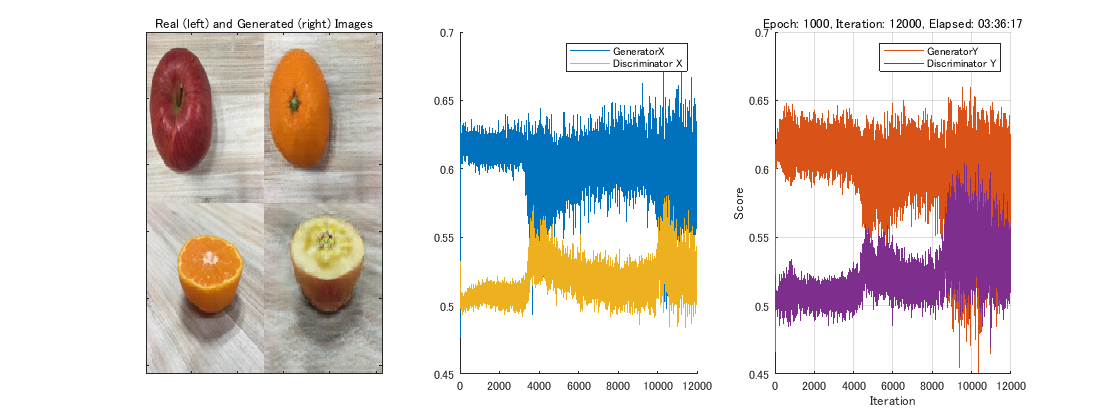

if doTraining 
    mkdir models
    iteration = 0;
    start = tic;
    
    for epoch = 1:numEpochs
        
        % Reset and shuffle training datastore
        reset(cgimdsTrain);
        cgimdsTrain = cgimdsTrain.shuffle(); 
        
        % Loop over mini-batches
        while hasdata(cgimdsTrain)
            iteration = iteration + 1;
            
            % Read mini-batch of data into table
            data = cgimdsTrain.read(); 
            
            % Ignore last partial mini-batch of epoch.
            if size(data,1) < miniBatchSize
                continue
            end
                
            % Extract batch of images from table 
            imageX = cat(4,data.X{:});
            imageY = cat(4,data.Y{:});
            
            % Convert mini-batch of data to dlarray and specify the dimension labels
            % 'SSCB' (spatial, spatial, channel, batch).
            imageX = dlarray(imageX,'SSCB');
            imageY = dlarray(imageY,'SSCB');
            
            % If training on a GPU, then convert data to gpuArray.
            if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
                imageX = gpuArray(imageX);
                imageY = gpuArray(imageY);
            end
            
            % Calculate the loss and gradients
            [generatorXGrad,generatorYGrad,discriminatorXGrad,discriminatorYGrad,scores,imagesOutXY,imagesOutYX] = ...
                dlfeval(@modelGradients,generatorXtoY,generatorYtoX,discrimatorX,discriminatorY,imageY,imageX,lambda);

            % Update parameters of generatorX
            [generatorYtoX.Learnables,avgGradGeneratorX,avgSqGradGeneratorX] = ...
                adamupdate(generatorYtoX.Learnables,generatorXGrad,avgGradGeneratorX,avgSqGradGeneratorX,iteration,learnRate,gradDecay,sqGradDecay);
            
            % Update parameters of generatorY
            [generatorXtoY.Learnables,avgGradGeneratorY,avgSqGradGeneratorY] = ...
                adamupdate(generatorXtoY.Learnables,generatorYGrad,avgGradGeneratorY,avgSqGradGeneratorY,iteration,learnRate,gradDecay,sqGradDecay);           
            
            % Update parameters of discriminatorX
            [discrimatorX.Learnables,avgGradDiscriminatorX,avgSqGradDiscriminatorX] = ...
                adamupdate(discrimatorX.Learnables,discriminatorXGrad,avgGradDiscriminatorX,avgSqGradDiscriminatorX,iteration,learnRate,gradDecay,sqGradDecay);
            
            % Update parameters of discriminatorY
            [discriminatorY.Learnables, avgGradDiscriminatorY, avgSqGradDiscriminatorY] = ...
                adamupdate(discriminatorY.Learnables,discriminatorYGrad,avgGradDiscriminatorY,avgSqGradDiscriminatorY,iteration,learnRate,gradDecay,sqGradDecay);
            
            % Update the scores plots
            subplot(1,3,2)
            addpoints(lineScoreGeneratorX,iteration,...
                double(gather(extractdata(scores{1}))));
            
            addpoints(lineScoreDiscriminatorX,iteration,...
                double(gather(extractdata(scores{3}))));            
            
            legend('GeneratorX','Discriminator X');
            
            subplot(1,3,3)        
            addpoints(lineScoreGeneratorY,iteration,...
                double(gather(extractdata(scores{2}))));
            
            addpoints(lineScoreDiscriminatorY,iteration,...
                double(gather(extractdata(scores{4}))));
            legend('GeneratorY','Discriminator Y');
            
           
            % Update the title with training progress information.
            D = duration(0,0,toc(start),'Format','hh:mm:ss');
            title(...
                "Epoch: " + epoch + ", " + ...
                "Iteration: " + iteration + ", " + ...
                "Elapsed: " + string(D))
           
            
            % Display the real and translated images at each iteration
            imageResultsYX = cat(2,imagesOutYX{1},imagesOutYX{2});
            imageResultsXY = cat(2,imagesOutXY{1},imagesOutXY{2});
            imageResults = extractdata(cat(1,imageResultsYX,imageResultsXY));
             
            subplot(1,3,1);
            image(imageAxes,imageResults(:,:,:,1))
            xticklabels([]);
            yticklabels([]);
            title("Real (left) and Generated (right) Images");
            
            drawnow;
        end

        % Save the model        
        if mod(epoch,saveFrequency) == 0 
            if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
                [generatorXtoY,generatorYtoX,discrimatorX,discriminatorY] = gather(generatorXtoY,generatorYtoX,discrimatorX,discriminatorY);
            end
            save(sprintf('models/cycleGAN_%04d.mat',epoch),'generatorXtoY','generatorYtoX','discrimatorX','discriminatorY')
        end
    end
    
else % if doTraining is false, load the trained model supplied with the repository
    load("cycleGAN_1000.mat") 
end

## Generate New Images Using Test Data

To generate new translated images, use the `predict` function of the generator networks with the test data. The test data is not seen by the network during training, and will indicate how well the network is doing at translating the images to and from each domain. 

Define the number of test images to use. The test data here contains two images of each domain. 

numTestIm = 2; 

Read images from the test data set and use the trained generators to generate new images. 

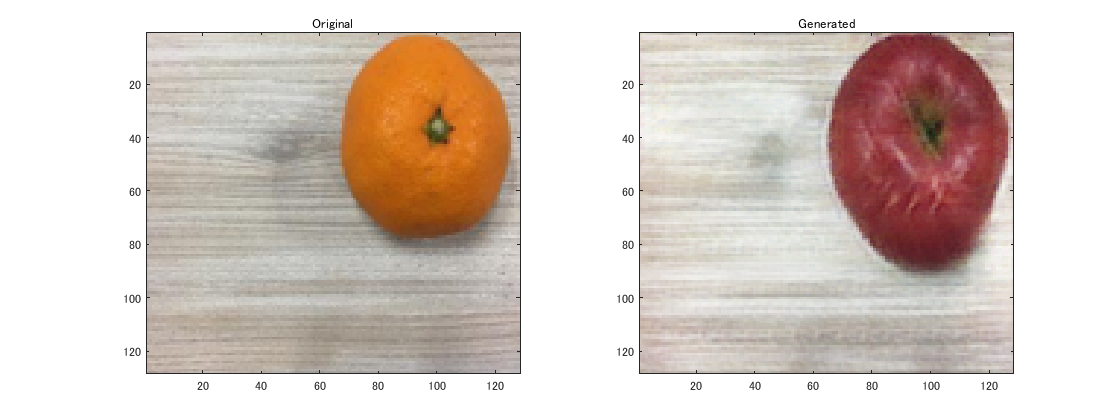

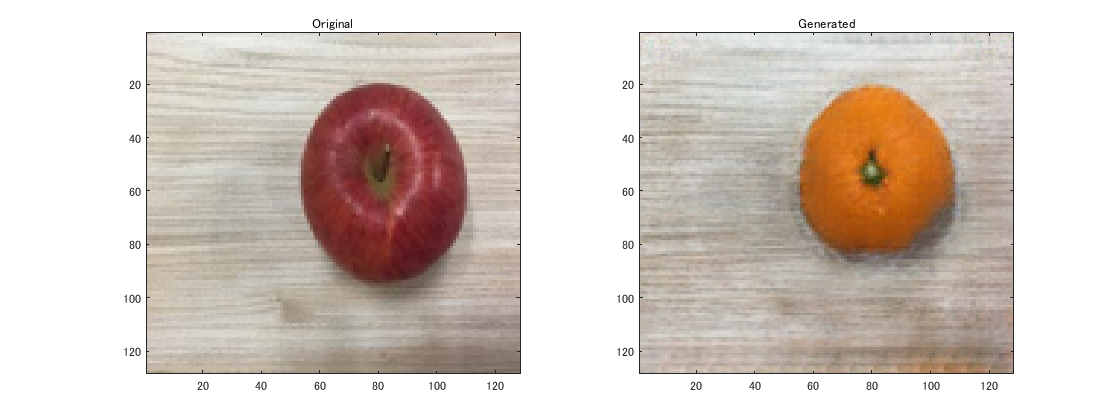

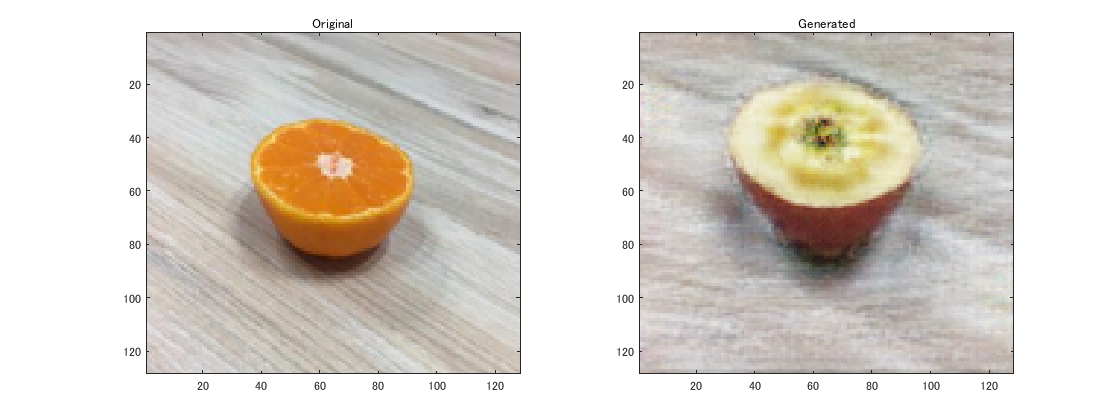

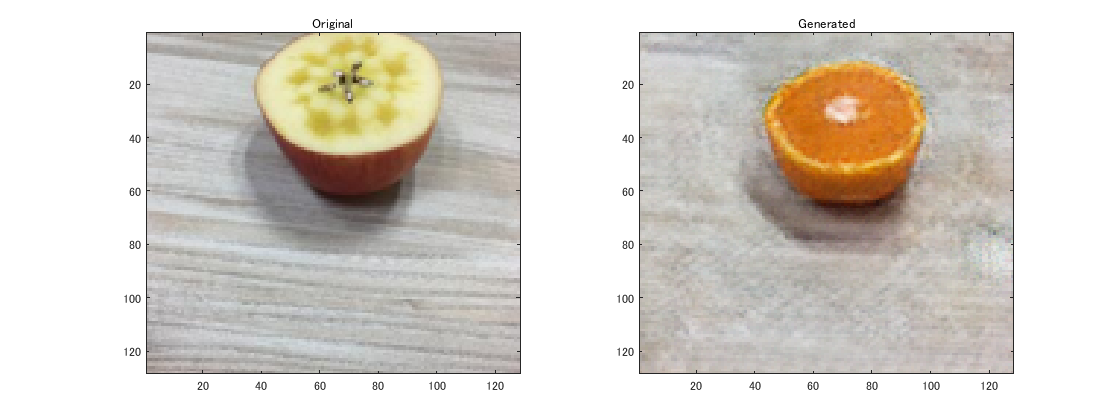

reset(cgimdsTest); % Reset the dataset

for k = 1:numTestIm
    dataTest = read(cgimdsTest); % read the data
      
    % Extract batch of images from table 
    imageXTest = cat(4, dataTest.X{:});
    imageYTest = cat(4, dataTest.Y{:});
    
    % Convert mini-batch of data to dlarray and specify the dimension labels
    % 'SSCB' (spatial, spatial, channel, batch).
    imageXTest = dlarray(imageXTest,'SSCB');
    imageYTest = dlarray(imageYTest,'SSCB');
    
    % If running on a GPU, then convert data to gpuArray.
    if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
        imageXTest = gpuArray(imageXTest);
        imageYTest = gpuArray(imageYTest);
    end
    
    % Generate translated images
    generatedImageY = forward(generatorXtoY,imageXTest);
    generatedImageX = forward(generatorYtoX,imageYTest); 
    
    % Display real and generated images
    showResults(imageXTest,generatedImageY,imageYTest,generatedImageX)

end

Using CycleGAN, you can convert images from one domain into another, without using specifically matched images from each domain. In this example, the model can identify whether the fruit in the image is whole or cut and generate an appropriate image of the other type of fruit. However, since the CycleGAN model is trained by unsupervised learning, the data set is important for generalized results.

## Supporting Functions

### Model Gradients Function

function [generatorXGrad,generatorYGrad,discriminatorXGrad,discriminatorYGrad,scores,imagesOutXY,imagesOutYX] = ...
    modelGradients(generatorY,generatorX,discriminatorX,discriminatorY,imageY,imageX,lambda)

    % Generate transformed images from input
    imageXGenerated = forward(generatorX,imageY);
    imageYGenerated = forward(generatorY,imageX);
    
    % Calculate predictions for real data with the discriminator network
    probRealX = forward(discriminatorX,imageX);
    probRealY = forward(discriminatorY,imageY);
    
    % Calculate predictions for generated data with the discriminator network
    probGeneratedX = forward(discriminatorX,imageXGenerated);
    probGeneratedY = forward(discriminatorY,imageYGenerated);
    
    % Calculate discriminator losses for real data
    discriminatorXLossReal = lossReal(probRealX);
    discriminatorYLossReal = lossReal(probRealY);
    
    % Calculate discriminator losses for generated data
    discriminatorXLossGenerated = lossGenerated(probGeneratedX);
    discriminatorYLossGenerated = lossGenerated(probGeneratedY);
    
    % Calculate total discriminator loss for each discriminator network
    discriminatorXLossTotal = 0.5*(discriminatorXLossReal + discriminatorXLossGenerated);
    discriminatorYLossTotal = 0.5*(discriminatorYLossReal + discriminatorYLossGenerated);
   
    % Apply generator to each generated image
    cycleImageX = forward(generatorX,imageYGenerated);
    cycleImageY = forward(generatorY,imageXGenerated);
    
    % Calculate cycle consistency loss between real and generated images
    cycleLossX = cycleLoss(imageX,cycleImageX,lambda);
    cycleLossY = cycleLoss(imageY,cycleImageY,lambda);
    
    % Calculate generator loss for generated images
    generatorLossX = lossReal(probGeneratedX);
    generatorLossY = lossReal(probGeneratedY);
   
    % Calculate total generator loss for each generator network
    generatorLossTotal = generatorLossX + cycleLossY + generatorLossY + cycleLossX;
    
    % Calculate scores of generators
    generatorXScore = mean(sigmoid(probGeneratedX),"all");
    generatorYScore = mean(sigmoid(probGeneratedY),"all");
    
    % Calculate scores of discriminators
    discriminatorXScore = 0.5*mean(sigmoid(probRealX),"all") + 0.5*mean(1-sigmoid(probGeneratedX),"all");
    discriminatorYScore = 0.5*mean(sigmoid(probRealY),"all") + 0.5*mean(1-sigmoid(probGeneratedY),"all");
    
    % Combine scores into cell array
    scores = {generatorXScore, generatorYScore, discriminatorXScore, discriminatorYScore};
    
    % Calculate generator gradients
    generatorYGrad = dlgradient(generatorLossTotal,generatorY.Learnables,'RetainData',true);
    generatorXGrad = dlgradient(generatorLossTotal,generatorX.Learnables,'RetainData',true);
    
    % Calculate discriminator gradients
    discriminatorXGrad = dlgradient(discriminatorXLossTotal,discriminatorX.Learnables);
    discriminatorYGrad = dlgradient(discriminatorYLossTotal,discriminatorY.Learnables);
    
    % Return first example image of mini-batch transforming domain X into domain Y
    imagesOutXY = {imageX,imageYGenerated};
    % Return example image transforming domain X into domain Y
    imagesOutYX = {imageY,imageXGenerated};
end


### Loss Functions


function loss = lossReal(probability)
    loss = mean((probability-1).^2,'all');
end

function loss = lossGenerated(probability)
    loss = mean((probability).^2,'all');
end

function loss = cycleLoss(imageReal,imageGenerated,lamda)
    loss = mean(abs(imageReal-imageGenerated),"all")*lamda;
end

### Show Results Function 

function showResults(imageXTest,generatedImageY,imageYTest,generatedImageX)

    % Generate axes for plotting real and generated images
    h1 = figure;
    h1.Position(3) = 2*h1.Position(3);
   
    for j = 1:2
        axesXY(j) = subplot(1,2,j);       
    end
    
    h2 = figure;
    h2.Position(3) = 2*h2.Position(3);
    for j = 1:2
        axesYX(j) = subplot(1,2,j);
    end    
    
    % Plot each image
    imagesc(axesXY(1),extractdata(imageXTest));
    title(axesXY(1),"Original")
    
    imagesc(axesXY(2),extractdata(generatedImageY));
    title(axesXY(2),"Generated")
    
    imagesc(axesYX(1),extractdata(imageYTest));
    title(axesYX(1),"Original")
    
    imagesc(axesYX(2),extractdata(generatedImageX));
    title(axesYX(2),"Generated")

    drawnow();
end

## Reference

[1] Zhu, Jun-Yan, Taesung Park, Phillip Isola, and Alexei A. Efros. “Unpaired Image-to-Image Translation Using Cycle-Consistent Adversarial Networks.” In *2017 IEEE International Conference on Computer Vision (ICCV)*, 2242–51. Venice: IEEE, 2017. [https://doi.org/10.1109/ICCV.2017.244](https://doi.org/10.1109/ICCV.2017.244).

[2] Li, Chuan, and Michael Wand. “Precomputed Real-Time Texture Synthesis with Markovian Generative Adversarial Networks.” In *Computer Vision – ECCV 2016*, edited by Bastian Leibe, Jiri Matas, Nicu Sebe, and Max Welling, 9907:702–16. Cham: Springer International Publishing, 2016. [https://doi.org/10.1007/978-3-319-46487-9_43](https://doi.org/10.1007/978-3-319-46487-9_43).

Copyright 2019-2020 The MathWorks, Inc.